# Average Electricity Usage in 1990 and 2019

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

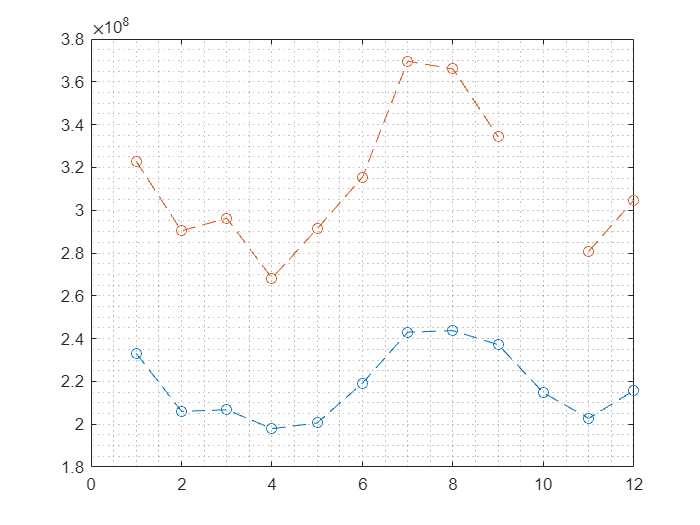

com = readmatrix("./data/electricity.xlsx", Sheet='com');
res = readmatrix("./data/electricity.xlsx", Sheet='res');
ind = readmatrix("./data/electricity.xlsx", Sheet='ind');

usage = ind + res + com;
firstYear = usage(:, 1);
lastYear = usage(:, end);
plot(1:12, firstYear, "o--")
grid minor
hold on
plot(1:12, lastYear, "o--")
hold off

## Task 1

The total electricity usage data for 1990 and 2019 have been extracted and saved in vectors `firstYear` and `lastYear` respectively.  You can see in the plot in the live script that the electricity usage in 2019 is higher than in 1990.

avg1990 = mean(firstYear)

avg1990 = 2.1838e+08

avg2015 = mean(lastYear)

avg2015 = NaN

## Task 2

The average electricity price for 2019 was `NaN`.  This is because there are missing values in `lastYear`.

You can identify and count missing values in a vector.  To identify missing values in a vector, use the `isnan` function.

`isnan``(``v``)`

The output is a logical vector where missing values are marked with a `1` for true.

missing2019 = isnan(lastYear)

missing2019 = 12×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


## Task 3

You can count the number of missing values with the `nnz` (number non-zero) function.

`nnz``(``vLogical``)`

numNaNs = nnz(missing2019);

## Task 4

You can ignore missing values in the `mean` calculation by using the `"omitnan"` flag.

`mean``(``v``,``"omitnan"``)`

avg2015 = mean(lastYear, "omitnan")

avg2015 = 3.1272e+08